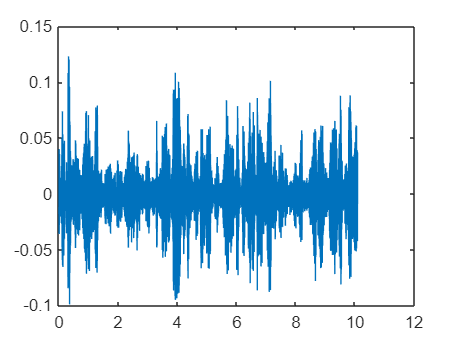

clc
clear all
load Observation_wb.mat
Array_1 = audioread("Array_output_01.wav");
Array_2 = audioread("Array_output_02.wav");
Array_3 = audioread("Array_output_03.wav");
Array_4 = audioread("Array_output_04.wav");
soundsc(Array_1,16000,16);
t = 0:1/16000:161424/16000;
plot(t,Array_1);

f = 0:161424

f =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


f = (f*16000/161425)-8000

f = 	1.0e+03 *

   -8.0000   -7.9999   -7.9998   -7.9997   -7.9996   -7.9995   -7.9994   -7.9993   -7.9992   -7.9991   -7.9990   -7.9989   -7.9988   -7.9987   -7.9986   -7.9985   -7.9984   -7.9983   -7.9982   -7.9981   -7.9980   -7.9979   -7.9978   -7.9977   -7.9976   -7.9975   -7.9974   -7.9973   -7.9972   -7.9971   -7.9970   -7.9969   -7.9968   -7.9967   -7.9966   -7.9965   -7.9964   -7.9963   -7.9962   -7.9961   -7.9960   -7.9959   -7.9958   -7.9957   -7.9956   -7.9955   -7.9954   -7.9953   -7.9952   -7.9951


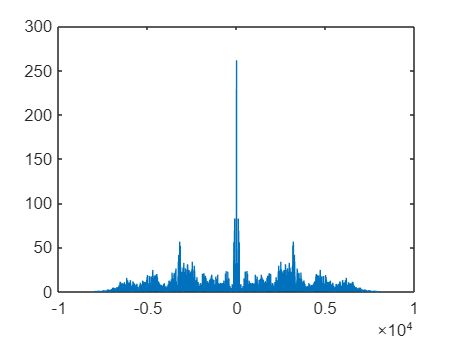

plot(f,abs(fftshift(fft(Array_1))));

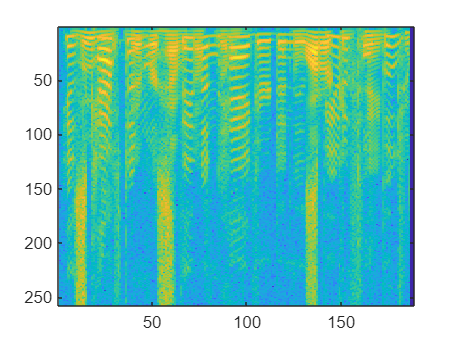

win = hann(512);
nfft = 512;
inc = 256;
shortfft = zeros(nfft/2+1,fix(size(X,1)/inc)+1,size(X,2));
a = 0;
for i = 0:inc:(size(X,1)-nfft);
    a = a+1;
    for j = 1:size(X,2);
        w = win.*X(i+1:i+nfft,j);
        t = fft(w,nfft);
        shortfft(:,a,j) = t(1:nfft/2+1);
    end
end
imagesc((real(10*log10(shortfft(:,:,1)))));

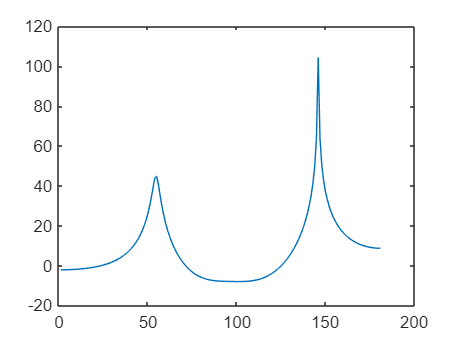

p_value = zeros(nfft/2+1,181);
for i = 1:(nfft/2+1)
    sfft = zeros(a,size(X,2));
    for j = 1:a
        for k = 1:4
            sfft(j,k) = shortfft(i,j,k);
        end
    end
    [c,b] = Pmusic_g(0.025,sfft,(i-1)/512*16000);
    for j = 1:181
      p_value(i,j) = 1./c(j);
    end
end
ans = zeros(181,1);
for i = 1:257
    ans(:,1) = ans(:,1) + p_value(i,:)';
end
ans = 257./ans;
plot(real(10*log(ans)));

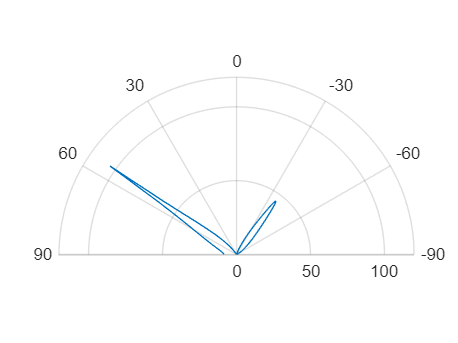

figure
pax = polaraxes;
polaraxes(pax)
polarplot(b,real(10*log(ans')));
pax.ThetaZeroLocation = 'top';
pax.ThetaLim = [-90,90];

p_value=ans;
theta = -90:1:90;    
n_source = 2;
P_middle = abs(p_value(2:end-1));
P_front = abs(p_value(1:end-2));
P_back = abs(p_value(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(p_value(1));P_middle;abs(p_value(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: -36 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 55 deg
